## Q1

Let's use the 4 cornors of each books as the desired points

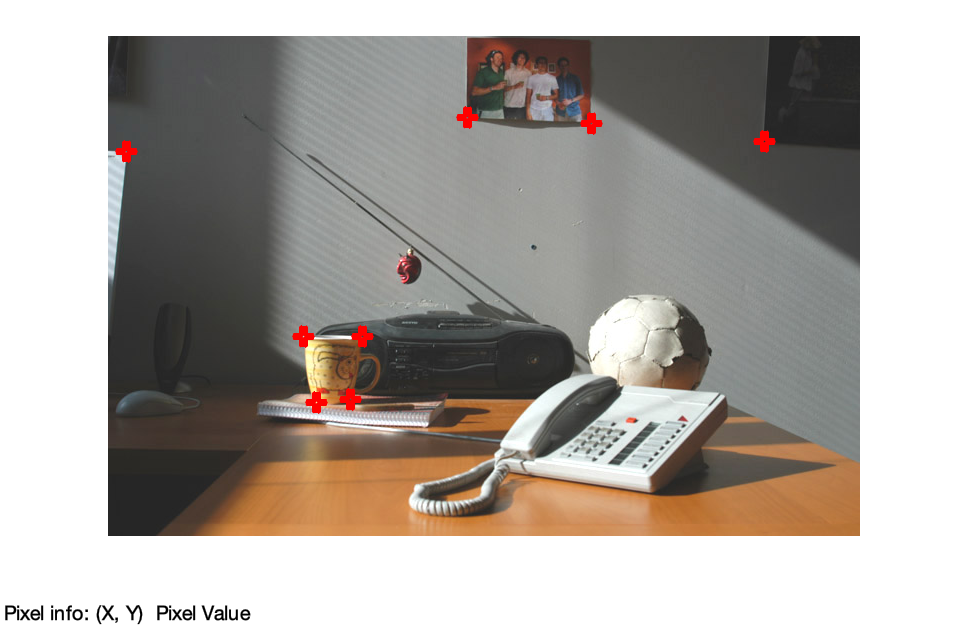

I1 = imread('p21.jpg');
imshow(I1);
impixelinfo;
hold on;
plot(484,88, 'ro', 'LineWidth', 5);
plot(360,82, 'ro', 'LineWidth', 5);
plot(657,106, 'ro', 'LineWidth', 5);
plot(19,116, 'ro', 'LineWidth', 5);
plot(196,301, 'ro', 'LineWidth', 5);
plot(255,301, 'ro', 'LineWidth', 5);
plot(209,367, 'ro', 'LineWidth', 5);
plot(243,364, 'ro', 'LineWidth', 5);
hold off;

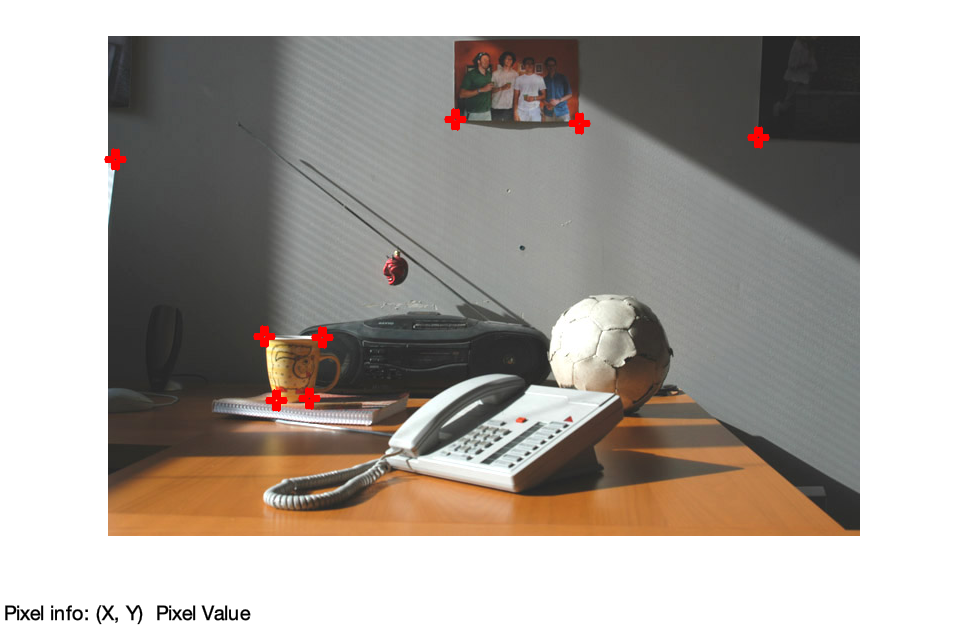

I2 = imread('p22.jpg');
imshow(I2);
impixelinfo;
hold on;
plot(472,88, 'ro', 'LineWidth', 5);
plot(348,84, 'ro', 'LineWidth', 5);
plot(651,102, 'ro', 'LineWidth', 5);
plot(8,124, 'ro', 'LineWidth', 5);
plot(157,301, 'ro', 'LineWidth', 5);
plot(215,302, 'ro', 'LineWidth', 5);
plot(169,365, 'ro', 'LineWidth', 5);
plot(202,363, 'ro', 'LineWidth', 5);
hold off;

Now load 8 points and compute F

L=[484,88;360,82;657,106;19,116;196,301;255,301;209,367;243,364];

R=[472,88;348,84;651,102;8,124;157,301;215,302;169,365;202,363];

F=Find_F(L,R,true);
disp('The Fundmental matrix F is');

The Fundmental matrix F is


disp(F);

   -0.0000   -0.0000    0.0039
    0.0000    0.0000   -0.0003
   -0.0041   -0.0011    0.2913



disp('The rank of F is');

The rank of F is


disp(rank(F));

     2



## Q2

Use RANSAC function

I1 = imread('p21.jpg');
I2 = imread('p22.jpg');
[wide,long,chan]=size(I1);
figure; ax = axes;
[F,pair]=RANSAC_F(I1,I2,0.01,30,5000,8);
%F=SurfFeaturepoints2("p11.jpg","p12.jpg")
disp(pair);

   304   234     1   290   236     1
   375    60     1   363    62     1
   304   396     1   245   394     1
   426    79     1   413    80     1
   322   236     1   308   238     1
   540   321     1   492   321     1
   371   272     1   360   274     1
   414    24     1   401    25     1
   509   426     1   380   427     1
   397   408     1   285   407     1
   434    74     1   422    75     1
   392    79     1   380    81     1
   438    47     1   425    47     1
   213   388     1   164   385     1
   368    70     1   356    72     1
   472    83     1   460    83     1
   305   225     1   292   227     1
   421   429     1   306   428     1
   412    80     1   399    82     1
   409    83     1   396    85     1
   217   355     1   175   354     1
   443    83     1   430    83     1
   460    66     1   447    66     1
   433    63     1   420    63     1
   439    70     1   427    71     1
   425   361     1   321   360     1
   402    78     1   389    80     1
 

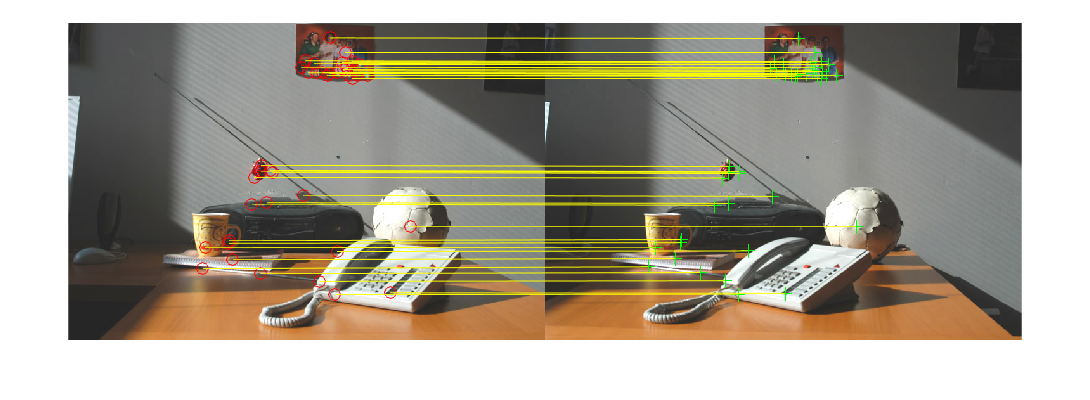

showMatchedFeatures(I1,I2,pair(:,1:2),pair(:,4:5),'montage','Parent',ax);

## Q3

Find epipoles e1 and e2

e1=null(F');
e2=null(F);

let e1,e2 = (eu,ev,1) 

e1=e1./e1(3);
e2=e2./e2(3);

Calculate H1

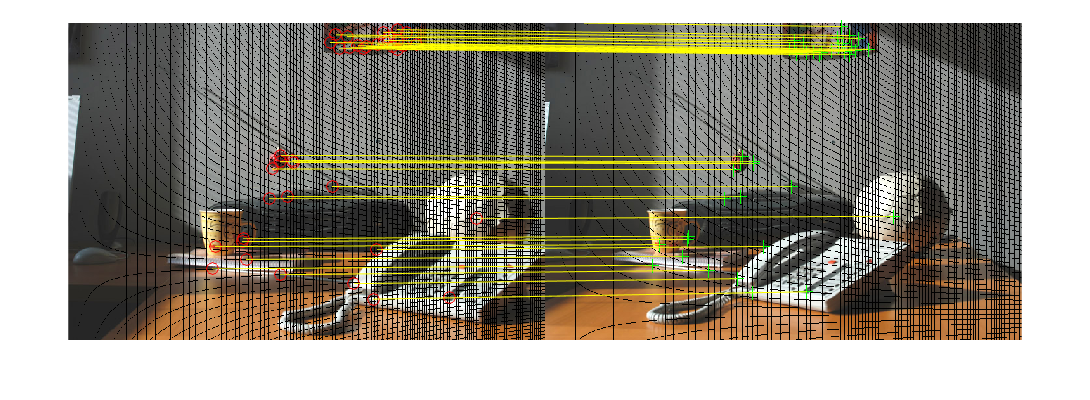

h1=find_h(e1);
h2=find_h(e2);
new_img=apply_homo(I1,h1);
points1=transfer_points(pair(:,1:3),h1);
new_img2=apply_homo(I2,h2);
points2=transfer_points(pair(:,4:6),h2);

showMatchedFeatures(new_img,new_img2,points1(:,1:2),points2(:,1:2),'montage','Parent',ax);